% The x, r, and y below are for testing. Comment them out and add yor own
% data to the sample data at the end of the comments, and uncomment your
% Script for the linear fit of data. The independent values are
% in the x array and the matched dependent values are in the y array.
% You also need to enter the confidence level, typically 95%. The values
% that are calculated and displayed are:
%% 1. Beta_hat_1 (the best-fit slope)
%% 2. Beta_hat_0 (the best-fit y-intercept)
%% 3. The Root Mean Square Residual, Se
%% 4. The Standard Error for beta0, Sbeta0
%% 5. The Standard Error for beta1, Sbeta1
%% 6. The confidence intervals for beta1 and beta0.
% After calculating these quantities, the script plots the original data,
% the best fit line, and the upper and lower bounds for the confidence
% interval on the best fit line.
x = [0.017 0.006 0.004 0.002 0]; % Uncomment and add your own data
y = [933 653 496 38.07 15.8]; % Uncomment and add your own data
confLev = 0.95; % The confidence level
N = length(y); % The number of data points
xbar = mean(x);
ybar = mean(y);
Sxx = dot((x-xbar),(x-xbar));
%Sxx = (x-xbar)*transpose(x-xbar);
% beta1 is the estimated best slope of the best-fit line
beta1 = dot((x-xbar),(y-ybar))/Sxx

beta1 = 5.3456e+04

% beta1 = ((x-xbar)*transpose(y-ybar))/Sxx
% beta0 is the estimated best-fit y-intercept of the best fit line
beta0 = ybar - beta1*xbar

beta0 = 117.1268

yfit = beta0 + beta1*x;
SSE = dot((y - yfit),(y - yfit)) % Sum of the squared residuals

SSE = 1.2700e+05

% SSE = (y - yfit)*transpose(y - yfit) % Sum of the squared residuals
Se = sqrt(SSE/(N-2)) % The Root Mean Square Residual

Se = 205.7533

Sbeta0 = Se*sqrt(1/N + xbar^2/Sxx)

Sbeta0 = 128.5376

Sbeta1 = Se/sqrt(Sxx)

Sbeta1 = 1.5474e+04

% tinv defaults to 1-sided test. We need 2-sises, hence:(1-0.5*(1-confLev))
StdT = tinv((1-0.5*(1-confLev)),N-2) % The Student's t factor

StdT = 3.1824

lambdaBeta1 = StdT*Sbeta1 % The 1/2 confidence interval on beta1

lambdaBeta1 = 4.9246e+04

lambdaBeta0 = StdT*Sbeta0 % The 1/2 confidence interval on beta0

lambdaBeta0 = 409.0640

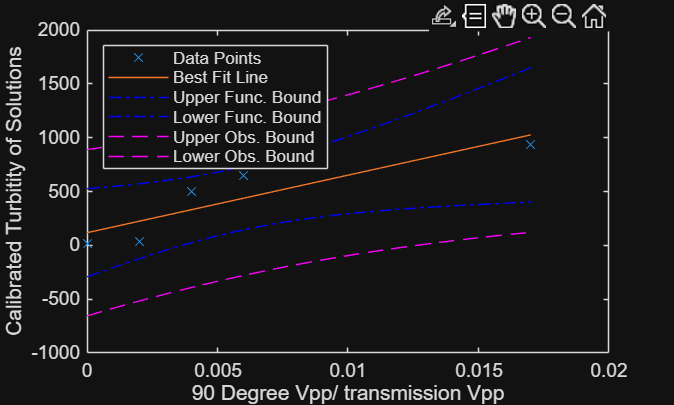

range = max(x) - min(x);
xplot = min(x):range/30:max(x); % Generate array for plotting
yplot = beta0 + beta1*xplot; % Generate array for plotting
Syhat = Se*sqrt(1/N + (xplot - xbar).*(xplot - xbar)/Sxx);
lambdayhat = StdT*Syhat;
Sy = Se*sqrt(1+1/N + (xplot - xbar).*(xplot - xbar)/Sxx);
lambday = StdT*Sy;
figure(1)
plot(x,y,'x')
hold on
plot(xplot,yplot)
plot(xplot,yplot+lambdayhat,'-.b',xplot,yplot-lambdayhat,'-.b')
plot(xplot,yplot+lambday,'--m',xplot,yplot-lambday,'--m')
xlabel('90 Degree Vpp/ transmission Vpp')
ylabel('Calibrated Turbitity of Solutions')
if beta1 > 0 % Fix this
   location = 'northwest';
else
   location = 'northeast';
end
legend('Data Points','Best Fit Line','Upper Func. Bound',...
   'Lower Func. Bound', 'Upper Obs. Bound', 'Lower Obs. Bound',...
   'Location', location)
hold off